# AERO60007 Control Systems: Quadrotor Control Pre-lab

This live script walks you through the derivation of the equations of motion for a quadrotor vehicle, followed by the development of state space controllers using these equations. The controllers developed are tested within the [Parrot Mambo Minidrone Simulink Environment](https://www.mathworks.com/help/supportpkg/parrot/index.html?s_tid=CRUX_lftnav), which is used as part of the [Mathworks Minidrone Competition](https://uk.mathworks.com/academia/student-competitions/minidrones.html).

## Learning Outcomes

By the end of this activity, you should be able to:

- Compute the matrices used in linear controller design from a given nonlinear system model.

- Explain how the existing PID controller for the position works

- Design and implement LQR and pole placement controllers for quadrotor position and velocity control.

- Explain the relationship between pole locations and system response.

- Augment controllers with integral action and feedforward terms to improve their performance. 

- Implement all of the controllers designed within the provided Simulink framework.

## **Important Considerations in the Design Process**

The main goal of this pre-lab is for you to design a controller that will be tested on hardware in real-time in the lab. Though the Simulink model here is quite detailed, there will inevitably be some mismatches between the Simulink model and reality (otherwise there would be no need for feedback). 

It is therefore crucial that you test the robustness of your design during simulations. For example, you should explore how errors in the parameters, such as the mass or other constants of the controller and Simulink model, affect closed-loop performance. It is therefore  important for you to demonstrate how you have incorporated this in the script below.

Always have a detailed look at the magnitudes and rates of the inputs and states signals that you get in closed-loop from your simulation. Often the simulation might seem to work fine and the response stable, but the magnitudes would not be physically realisable. If the magnitudes are not realistic, modify your design appropriately.

You should be systematic in your design process. Use quantitative (i.e. numeric) metrics to compare two different designs in your script below. You might, for example, wish to compare two designs in terms of the settling time, rise time and overshoot, as well as the sensitivity of these metrics with regards to errors in the model parameters.

## Derive the Quadrotor State Equations

In order to design the required controllers, the state-space equations first need to be derived. For the derivation, the following coordinate systems and motor numerations are assumed. Note that the z-axis is pointing downwards.

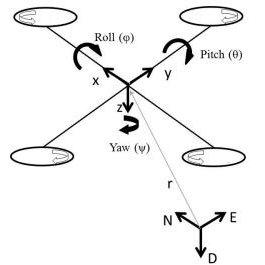

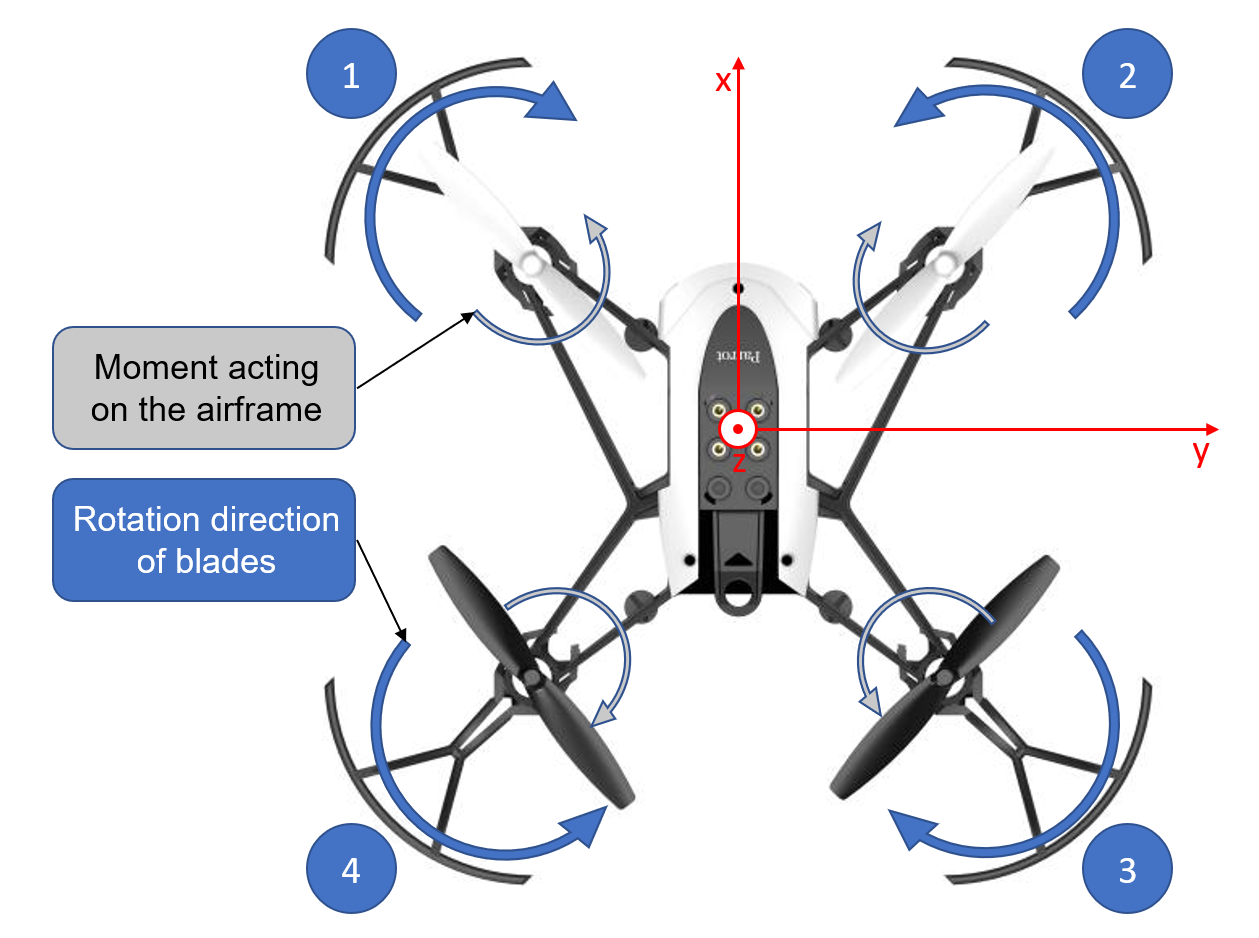

The derivation presented in this live script is adapted from [here](https://charlestytler.com/quadcopter-equations-motion/). Note the difference in motor mapping, the use of thrust as a control input, the use of inerial frame velocity, and the difference in the positive direction of K, L, and M moments in our derivation.

The Symbolic Toolbox is a perfect tool to derive the state equations and save them as MATLAB Functions. First, let's declare the symbolic variables for states, inputs (MVs) and parameters.

%Clear the variables from the workspace
clear;
% Set this variable to false if generating figures for evaluation purposes.
% Set as true otherwise.
req_input = true;
% Suppress warnings related to deprecated environment block
warning('off','Simulink:VariantAdvisorChecks:ObsoleteSlEnvironmentControllerBlockCauseWithArg')
%% Create real symbolic variables for states, inputs, MVs and parameters
syms input_1 input_2 input_3 input_4 Ixx Iyy Izz k l m b g real
syms x y_vel z phi theta psi vx vy vz p q r real

where:

**States **

$x$: x position in global coordinates [m]

$y$: y position in global coordinates [m]

$z$: z position in global coordinates [m]

$\phi$ (phi): roll angle [rad]

$\theta$ (theta): pitch angle [rad]

$\psi$ (psi): yaw angle [rad]

$$v_x$
$: x velocity in inertial frame of reference [m/s]

$$v_y$
$: y velocity in inertial frame of refenence [m/s]

$$v_z$$: z velocity in inertial frame of reference [m/s]

$p$: angular velocity around x axis of body coordinate system [rad/s]

$q$: angular velocity around y axis of body coordinate system [rad/s]

$r$: angular velocity around z axis of body coordinate system [rad/s]

**Control Inputs**

$$T_i$$: Thrust produced by rotor $$i$$ along the [0;0;1] axis [N] ($$-$ve$ is upwards).

**Parameters**

$g$: gravitational acceleration [m/s^2]

$b$: rotor drag constant [kg*m^2]

$k$: rotor lift constant [kg*m]

$l$: moment arm between rotor and centre of mass [m]

$I_{ii}$ (Iii): diagonal elements of inertia matrix [kg*m^2]

For the Parrot Mambo, the parameters are:

load UAV_NominalParameters % Make sure this is in your path
%IxxVal  %Units kg * m^2
%IyyVal  %Units kg * m^2
%IzzVal  %Units kg * m^2
%kVal  %Units N * s^2 = kg * m
%lVal  %Units m
%mVal  %Units kg
%bVal  %Units N * m * s^2= kg * m^2
gVal = 9.81; %Units kg * m / s^2

paramValues = [IxxVal IyyVal IzzVal kVal lVal mVal bVal gVal]

paramValues =     0.0001    0.0001    0.0001    0.0000    0.0441    0.0630    0.0000    9.8100


During the flight, the quadcopter's coordinate system will be rotating. Therefore, we need to relate it to the global coordinates using a rotational matrix

%R-ZYX Euler
Rz = [cos(psi), -sin(psi), 0;
    sin(psi), cos(psi), 0;
    0, 0, 1];
Ry = [cos(theta), 0, sin(theta);
    0, 1, 0;
    -sin(theta), 0, cos(theta)];
Rx = [1, 0, 0;
    0, cos(phi), -sin(phi);
    0, sin(phi), cos(phi)];

% Rotation matrix from body frame to inertial frame
R_Euler = Rz*Ry*Rx;

The thrust generated by the rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Recall that our input for motor $i$ is simply the thrust $$$T_i$$$ which it generates. Therefore, the total thrust generated is 

% Thrust force
Fz = (input_1 + input_2 + input_3 + input_4);

The produced thrust also generates moments around the x and y-axis:


$$$$L_i=\pm l \cdot T_i$$$$



$$$$M_i=\pm l \cdot T_i$$$$


where $L$ and $M$ are moments acting on the x and y-axis respectively and $l$ is the moment arm of the thrust. Due to symmetry of the drone the $l$ value is the same for both axes.

The thrust generated by a single rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Additionaly, the drag created at the blades needs to be counteracted by motor torque:


$$$N_i = \frac{\pm R \cdot Drag}{2} = \pm \frac{R}{4} \rho c_D V_{tip,i}^2 \cdot A_{ref}= \pm \frac{1}{4} \rho c_D R^3 \cdot A_{ref} \cdot \omega_i^2 = \pm b \cdot \omega^2_i = \pm \frac{b}{k} \cdot T_i $$$


where $c_D$ is the drag coefficient related to the blade geometry. Where all of the constant variables except for $$F_{z_i}}$$  and $k$ are substituted by a single parameter $b$. Therefore, the total moments acting on the vehicle are:

% Moments
L = l * (- input_1 + input_2 + input_3 - input_4);
M = l * (- input_1 - input_2 + input_3 + input_4);
N = (b ./ k) * (input_1 - input_2 + input_3 - input_4);

Note the positive moments are defined by the right-hand rule. 

Having defined the forces and moments acting on the system and the rotation matrix, we can start deriving equations of motion. Firstly, the rate of change of the global frame positions is simply the velocity vector in the global frame of reference:

% Position in global frame of reference
f(1:3) = [vx; vy; vz];

The Euler angles rates are (see [Detailed derivation](https://charlestytler.com/quadcopter-equations-motion/)):

% Euler angles rates
f(4) = p + (q * sin(phi) + r * cos(phi)) * tan(theta);
f(5) = q * cos(phi) - r * sin(phi);
f(6) = (q * sin(phi) + r * cos(phi)) / cos(theta);

The linear acceleration of the system is obtained from Newton's Second Law, with the thrust vector rotated to the inertial frame:

% Acceleration in inertial frame
f(7:9) = R_Euler*[0;0;Fz]/m + [0;0;g];

Using the vector transport theorem, the angular acceleration of the system can be defined as (see [Detailed derivation](https://charlestytler.com/quadcopter-equations-motion/)): 

% Rotational Acceleration
f(10) = (L + (Iyy - Izz) * q * r) / Ixx;
f(11) = (M + (Izz - Ixx) * p * r) / Iyy;
f(12) = (N + (Ixx - Iyy) * p * q) / Izz;

Use MATLAB [subs](https://www.mathworks.com/help/symbolic/subs.html) function to replace the parameter variables with their respective values and [simplify](https://www.mathworks.com/help/symbolic/simplify.html) the result:

% Replace parameters
f = subs(f, [Ixx Iyy Izz k l m b g], paramValues);      
f = simplify(f);                                        

Let us now group the states and normalised control inputs:

% Group symbolic variables
state = [x y_vel z phi theta psi vx vy vz p q r];
control = [input_1, input_2, input_3, input_4];

Having now defined the state equations, obtain their Jacobians using [jacobian](https://www.mathworks.com/help/symbolic/sym.jacobian.html)

% Calculate linearization
A = jacobian(f,state);
B = jacobian(f,control);

We can also find the motor speeds required to achieve equilibrium at given coordinates. 

To maintain stable position and orientation, all velocities need to be zero. This also means the pitch and yaw angle need to be zero as well.

Finally, look at the state equations and answer the following question: Does the position of the drone affect equilibrium? What would be the most convenient point to linearise at?

As an example, one can compute the equilibrium input when the states are all zero using MATLAB functions [subs](https://www.mathworks.com/help/symbolic/subs.html) and [solve](https://www.mathworks.com/help/symbolic/solve.html):

f_StatesZero = subs(f, state, zeros(1,12));                       
[input_Eq1, input_Eq2, input_Eq3, input_Eq4] = solve(f_StatesZero == 0, control);     
input_Eq = double([input_Eq1 input_Eq2 input_Eq3 input_Eq4])               

input_Eq =    -0.1545   -0.1545   -0.1545   -0.1545


%Save the result in a mat file
save('Equilibrium inputs', 'input_Eq')

## Ensure that the Dependencies for the Parrot Model are Installed Properly

Before continuing, it is important to ensure that all of the dependencies for the parrot model are installed. Please make sure that [Simulink](https://uk.mathworks.com/products/simulink.html), the [Aerospace Toolbox](https://uk.mathworks.com/products/aerospace-toolbox.html?requestedDomain=), [Aerospace Blockset](https://uk.mathworks.com/products/aerospace-blockset.html?requestedDomain=), the [Computer Vision Toolbox](https://uk.mathworks.com/products/computer-vision.html), the [Signal Processing Toolbox](https://uk.mathworks.com/products/signal.html), the [Simulink 3D Animation Add-On](https://uk.mathworks.com/products/3d-animation.html), and the [Simulink Support Package for Parrot Minidrones](https://uk.mathworks.com/matlabcentral/fileexchange/63318-simulink-support-package-for-parrot-minidrones) are all installed on your machine. Note that when installing the Parrot add-on you might be asked to setup the Parrot hardware and connect the drone to your computer - this is not necessary for you to run this script, so you can skip this step when asked.

The code below verifies that everything you need to run the model is properly set up.

ver_info = struct2array(ver);
simulink_installed = contains(ver_info, 'Simulink')

simulink_installed = logical
   1


aero_installed = contains(ver_info, 'Aerospace Toolbox')

aero_installed = logical
   1


aero_block_installed = contains(ver_info, 'Aerospace Blockset')

aero_block_installed = logical
   1


cv_installed = contains(ver_info, 'Computer Vision Toolbox')

cv_installed = logical
   1


signal_installed = contains(ver_info, 'Signal Processing Toolbox')

signal_installed = logical
   1


threeD_installed = contains(ver_info, 'Simulink 3D Animation')

threeD_installed = logical
   0


parrot_support_installed = isParrotSupportPkgInstalled

parrot_support_installed = logical
   0


if simulink_installed && aero_installed && aero_block_installed && cv_installed && signal_installed && threeD_installed && parrot_support_installed
    disp('All dependencies are met.')
else
    error('Missing model dependencies. Ensure that all of the requirements are properly installed before proceeding.')
end

Missing model dependencies. Ensure that all of the requirements are properly installed before proceeding.

Additionally, ensure that you are running Simulink R2022b or newer. Note that you should be able to run this script in MATLAB Online if you wish.

## Examine the Existing PID Controller

In order to familiarize yourself with the Parrot environment, begin by examining the default PID controller used by the simulation environment. 

Note that the controller is a discrete-time PID controller. The sample period `Ts` can be found in `utilities/startVars.m`

Why do you think the controller is organized as seen? Why is the x and y position control linked to attitude control, while altitude control is mostly decoupled? Whenever you are done examining the controller, press 'Enter' to continue.

if req_input
open_system('PID/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

Next, try running the simulation and examine how it performs.

if req_input
close_system('flightControlSystem');
end
pidProj = openProject('PID/HoverWithPID.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(1)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(2)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
if req_input
input('Press "Enter" key to continue...')
end

Once done, press 'Enter' again to move on to the next section.

if req_input
close(pidProj)
end

## Design an LQR Controller for Position Control

Using the equations of motion derived above, design an LQR controller for position and yaw control of the quadrotor vehicle. The reference your controller will recieve consists of the desired position and yaw, augmented with zeros for all of the other states. Show how you obtain the gains you choose to use. Define your desired output through a $$C$$ matrix and use that in trying to obtain your controller gains. 

% defining y (output vector) as a 4x1
y_pos = [state(1:3), state(6)];

% defining C matrix (sensor matrix): only have reference for yaw, and
% velocities (4x12)
C0_pos = zeros(4,12);
C0_pos(1,1) = 1;
C0_pos(2,2) = 1;
C0_pos(3,3) = 1;
C0_pos(4,6) = 1;

% defining D matrix (direct term), 4x4 zeros implying that control signal u
% does not influence the output directly (no feedforward at this stage)
D0_pos = zeros(4,4);

% subbing in the equilibrium conditions into A and B matrices
% and convert to double 
A0_pos = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
B0_pos = double(subs(B, [state, control], [zeros(1,12), input_Eq]));

sys_pos = ss(A0_pos, B0_pos, C0_pos, D0_pos);

% quadratic cost function weightings and sample period
% Q = C'*C; % not used

Q1pos = diag([250 243.4710 82.9635 250 157.9276 203.8830 0 0 4.2026 25.9128 4.3707 116.6581]);

R = diag([1 1 1 1]);
Ts = 0.005; % to discretise continuous cost function

% obtain discrete gain matrix and eigenvalues of velocity controller
% of closed loop system
[K_pos,~,~] = lqrd(A0_pos, B0_pos, Q1pos, R, Ts);

% create a closed loop system
Bcl_p = B0_pos * K_pos;
Acl_p = A0_pos - B0_pos * K_pos;
Dcl_p = D0_pos;
Ccl_p = C0_pos;

Next, transfer the gains you have computed to the state-space block in the simulink model for the controller. Note that the controller operates in discrete time, so your design will have to be discretized. Additionally, consider the fact that the input to your state-space block ($$\mathbf{u}_k$$) is the error between your reference and estimated state.

if req_input
open_system('LQR/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

Then, run the simulation until you are satisfied with the performance of the system.

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(3)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(4)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

% get errors
E_x = rmse(cmds.ans.Data(1:11000,1), simInfo.estimatedStates.signals.values(1:11000,1))
E_y = rmse(cmds.ans.Data(1:11000,2), simInfo.estimatedStates.signals.values(1:11000,2))
E_z = rmse(cmds.ans.Data(1:11000,3), simInfo.estimatedStates.signals.values(1:11000,3))

if req_input
input('Press "Enter" key to continue...')
end

Once you're done, press 'Enter' again to move on to the next section.

close(lqrProj)

## Design an LQR Controller for Velocity Control

Now, repeat the LQR design process but for velocity and yaw tracking instead of position control. The reference your controller will receive consists of the desired velocity and yaw, augmented with zeros for all of the other states. If you attempt to design the controller as for the position control case, you will run into issues in computing your LQR gains because $$\left(A,Q^{1/2}\right)$$ is not detectable. 

Does the position error have any effect on the velocity tracking dynamics? What about attitude and angular velocity? Think about which subsystem of the full dynamics the controller should actually be designed for, and what the gains for the remainder of the system should be set to. Show how you obtain your gains in the code box below.

% defining y (output vector) as a 4x1
y_vel = [state(6:9)];

% defining C matrix (sensor matrix): only have reference for yaw, and
% velocities (4x12)
C0_vel = zeros(4,12);
C0_vel(1,6) = 1;
C0_vel(2,7) = 1;
C0_vel(3,8) = 1;
C0_vel(4,9) = 1;

% subbing in the equilibrium conditions into A and B matrices
% and convert to double 
A0_vel = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
B0_vel = double(subs(B, [state, control], [zeros(1,12), input_Eq]));

% quadratic cost function weightings and sample period
% Q = C'*C; % not used
Q1vel = diag([10e-20 10e-20 10e-20 0 0 0.015 0.001 0.001 2 0 0 0]);
Rvel = diag([1 1 1 1]) * 12;
Ts = 0.005; % to discretise continuous cost function

% obtain discrete gain matrix and eigenvalues of velocity controller
% of closed loop system
[K_vel,~,~] = lqrd(A0_vel, B0_vel, Q1vel, Rvel, Ts);

% create a closed loop system
Bcl_v = B0_vel * K_vel;
Acl_v = A0_vel - B0_vel * K_vel;
Ccl_v = C0_vel;

Next, transfer the gains to the simulation environment, remembering that they should be discretized

if req_input
open_system('LQR_vel/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

Once done, press 'Enter' to launch the full simulation model and examine the performance of the controller you designed. Take your time to iterate and achieve a suitable level of performance for the system.  

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(5)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(6)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

% output errors
E_u = rmse(cmds.ans.Data(1:11000,1), simInfo.estimatedStates.signals.values(1:11000,7))
E_v = rmse(cmds.ans.Data(1:11000,2), simInfo.estimatedStates.signals.values(1:11000,8))
E_w = rmse(cmds.ans.Data(1:11000,3), simInfo.estimatedStates.signals.values(1:11000,9))

if req_input
input('Press "Enter" key to continue...')
end

If you are happy with how your controller is doing, you can hit 'Enter' again to move on to the next section 

close(lqrProj)

## Design a Pole Placement Controller for Velocity Control

Repeat the task of designing a velocity tracking control, but use a pole placement approach instead of LQR this time. Try limiting all of your poles to being on the real line. 

How does moving the poles affect the rise time, settling time, and overshoot? Do you notice a difference in the way the response changes when you move dominant poles when compared to changing the other poles? 

The reference your controller will receive consists of the desired velocity and yaw, augmented with zeros for all of the other states.  Show how you obtain your gains in the code box below.

% subbing in the equilibrium conditions into A and B matrices
% and convert to double 
Asub = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
Bsub = double(subs(B, [state, control], [zeros(1,12), input_Eq]));
% defining C matrix (sensor matrix): only have reference for yaw, and
% velocities (4x12)
%not needed unless needed to create a state space
C = zeros(4,12);
C(1,6) = 1;
C(2,7) = 1;
C(3,8) = 1;
C(4,9) = 1;
%reduce matrix to 9 input states to help with poles
A_reduced = Asub(4:12,4:12);
B_reduced = Bsub(4:12,:);
%solve using pole placement 
poles = [-7 -7 -7 -2 -2 -2 -12 -20 -15]';
%place desired poles(stable as they are all in the left half plane of a
%continuous system. The gains are Kp
K_ninestates = place(A_reduced,B_reduced,poles);
% augment kp to a vector with dimension (1,12)
Kp_aug = zeros(4,12);
% add the previous states onto the augmented matrix
Kp_aug(:,4:12) = K_ninestates;
%create a state space system
sys = ss(0,zeros(1,12),zeros(4,1),-Kp_aug);
%for discrete system
sampletime = 0.005;
%convert continuous to dyanmic system
sysd=c2d(sys,sampletime);
%input in "K_final_dc" in simulink discrete state space model in "D"
%put sampletime variable in the sampletime space too in the discrete state space block
K_final_dc=sysd.D;

Next, transfer the gains you have computed to the state-space block in the simulink model for the controller.

if req_input
open_system('Pole Placement/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

Once done, press 'Enter' to launch the full simulation model and examine the performance of your controller.

if req_input
close_system('flightControlSystem');
end
ppProj = openProject('Pole Placement/HoverWithPolePlacement.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(7)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(8)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

E_u = rmse(cmds.ans.Data(1:11000,1), simInfo.estimatedStates.signals.values(1:11000,7))
E_v = rmse(cmds.ans.Data(1:11000,2), simInfo.estimatedStates.signals.values(1:11000,8))
E_w = rmse(cmds.ans.Data(1:11000,3), simInfo.estimatedStates.signals.values(1:11000,9))

if req_input
input('Press "Enter" key to continue...')
end

Press 'Enter' again to move on to the next section 

close(ppProj)

## Add Integral Action to the LQR Position Controller

When designing the position controller, you may have noticed the existence of a persistent altitude offset. We now attempt to fix this by augmenting the controller with an integral component. Choose the number of states you wish to add to your controller, and design your gains in the code box below.

% 1st method - manually choose Ki - this seems to control all states
% equally (using 2nd method)
% 
% AKI = 0; % continuous
% BKI = [1 1 1 0 0 1 0 0 0 0 0 0];
% Ki = 0.01 * [1; 1; 1; 1];
% CKI = -Ki;
% 
% A0_pos = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
% B0_pos = double(subs(B, [state, control], [zeros(1,12), input_Eq]));
% 
% QIpos = diag([250 243.4710 82.9635 250 157.9276 203.8830 0 0 4.2026 25.9128 4.3707 116.6581]); % from pos LQR
% RIpos = diag([1 1 1 1]); % from pos LQR
% Ts = 0.005;
% 
% Kp_pi = lqrd(A0_pos, B0_pos, QIpos, RIpos, Ts);
% DKI = -Kp_pi; % same as earlier Kp gains
% 
% sys = ss(AKI, BKI, CKI, DKI); % continuous
% sysd = c2d(sys, Ts); % discretise system
% 
% % input into simulink sysd.A, B C and D

% --------------------------------------------------------

% 2nd method: uses augmented state space so can control multiple states
% using integral

Ts = 0.005;

% set initial conditions for error terms (as 0)
A0_pos = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
B0_pos = double(subs(B, [state, control], [zeros(1,12), input_Eq]));
C0_pos = zeros(4,12);
C0_pos(1,1) = 1; C0_pos(2,2) = 1; C0_pos(3,3) = 1; C0_pos(4,6) = 1;


% state augmentation
A0i = [A0_pos zeros(12,4); C0_pos zeros(4,4)];
B0i = [B0_pos; zeros(4,4)];

% only need for Q tuning
C0i = [C0_pos zeros(4,4); zeros(4,12) eye(4)];

% Q1pi = [0.008,0.005,4 0.005]; % yaw u v w
% Q2pi = [0.00001,0.00001,0.02,0.0005]; % last 4 for integral terms
% Qpi = diag([Q1pi Q2pi]);
% Qpi = C0i' * Qpi * C0i;

% pick Qpi manually
Qpi = diag([0.008, 0.005, 4, 0.0005, 0.0005, 0.005, 0.0005, 0.0005, 0.0005, 0.0005, 0.0005, 0.0005, 0.00001, 0.00001, 0.02, 0.0005]); % better response filling other terms
R = eye(4);

[K_posi, ~, ~] = lqrd(A0i, B0i, Qpi, R, Ts);

% change Ki manually
Kp_pos = K_posi(:,1:12); % dimensions 4x12
Ki_pos = zeros(4,12); % same dimensions as Kp
Ki_pos(:,1:3) = K_posi(:,13:15); % take last 4 terms of K matrix as integral terms but in controlling states
Ki_pos(:,6) = K_posi(:,16); % take last 4 terms of K matrix as integral terms but in controlling states

% controller state space
Acontrol_p = eye(12); % need to match C_control dimensions
Bcontrol_p = eye(12)*Ts;
Ccontrol_p = -Ki_pos;
Dcontrol_p = -Kp_pos;

Next, transfer your gains to the controller model. Think about how to represent your controller as a state space block where $$\mathbf{u}_k$$ is your reference error.

if req_input
open_system('LQR_integral/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

Then, run the simulation until you are satisfied with the performance of the system. Do you notice a decrease in the steady state error? 

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_integral/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(9)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(10)
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

% output error
E_x = rmse(cmds.ans.Data(1:11000,1), simInfo.estimatedStates.signals.values(1:11000,1))
E_y = rmse(cmds.ans.Data(1:11000,2), simInfo.estimatedStates.signals.values(1:11000,2))
E_z = rmse(cmds.ans.Data(1:11000,3), simInfo.estimatedStates.signals.values(1:11000,3))

if req_input
input('Press "Enter" key to continue...')
end

Once you're done, press 'Enter' again to move on to the next section.

close(lqrProj)

## Add Integral Action to the LQR Velocity Controller

Now do this again to add integral action to the LQR velocity controller. As usual, show how you obtain your gains here.

% 1st method - manually choose Ki - this seems to control all states
% equally - NO STATE AUGMENTATION (using 2nd method)

% AKI = 0; % continuous
% BKI = [0 0 0 0 0 1 1 1 1 0 0 0];
% Ki = 0.01 * [1; 1; 1; 1];
% CKI = -Ki;
% 
% A0_vel = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
% B0_vel = double(subs(B, [state, control], [zeros(1,12), input_Eq]));
% 
% QIvel = diag([10e-20 10e-20 10e-20 0 0 0.015 0.001 0.001 2 0 0 0]); % from vel LQR
% RIvel = diag([1 1 1 1]) * 12; % from vel LQR
% Ts = 0.005;
% 
% Kp_vi = lqrd(A0_vel, B0_vel, QIvel, RIvel, Ts);
% DKI = -Kp_vi; % same as earlier Kp gains
% 
% sys = ss(AKI, BKI, CKI, DKI); % continuous
% sysd = c2d(sys, Ts); % discretise system
% 
% % input into simulink sysd.A, B C and D

% ------------------------------------

% 2nd method: uses augmented state space so can control multiple states
% using integral

% x y z states are removed as we do not want to control these
% set initial conditions for error terms (as 0)
A0_vel = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
A0_vel = A0_vel(4:end,4:end);
B0_vel = double(subs(B, [state, control], [zeros(1,12), input_Eq]));
B0_vel = B0_vel(4:end,:);
% defining C matrix (sensor/observer matrix): only have reference for yaw and velocities (4x12)
C0_vel = zeros(4,12);
C0_vel(1,6) = 1; C0_vel(2,7) = 1; C0_vel(3,8) = 1; C0_vel(4,9) = 1;
C0_vel = C0_vel(:,4:end); % delete unwanted states x y z (rank is 9)

% defining D matrix (direct term), 4x4 zeros implying that control signal u
% does not influence the output directly (no feedforward at this stage)
D0_vel = zeros(4,4);

% state augmentation
A0i = [A0_vel zeros(9,4); C0_vel zeros(4,4)];
B0i = [B0_vel; zeros(4,4)];

% only need for Q tuning
C0i = [C0_vel zeros(4,4); zeros(4,9) eye(4)];

Q1vi = [2 5e-5 5e-5 2]; % yaw u v w
Q2vi = [0.02 0.00005 0.00005 0.02]; % last 4 for integral terms
Qvi = diag([Q1vi Q2vi]);
Qvi = C0i' * Qvi * C0i;
R = eye(4);

[K_veli, ~, ~] = lqrd(A0i, B0i, Qvi, R, Ts);

% change Ki manually
Kp_vel = zeros(4,3);
Kp_vel(:,4:12) = K_veli(:,1:9); % dimensions 4x12
Ki_vel = zeros(4,12); % same dimensions as Kp
Ki_vel(:,6:9) = K_veli(:,10:13); % take last 4 terms of K matrix as integral terms but in controlling states


% discrete controller state space
Acontrol_v = eye(12); % need to match C_control col. dimensions
Bcontrol_v = eye(12)*Ts;
Ccontrol_v = -Ki_vel;
Dcontrol_v = -Kp_vel;

Next, transfer your gains to the controller model.

if req_input
open_system('LQR_vel_integral/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

Once done, press 'Enter' to launch the full simulation model and examine how the addition of the integral term affects the performance of your controller.

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel_integral/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(11)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(12)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

% output errors
E_u = rmse(cmds.ans.Data(1:11000,1), simInfo.estimatedStates.signals.values(1:11000,7))
E_v = rmse(cmds.ans.Data(1:11000,2), simInfo.estimatedStates.signals.values(1:11000,8))
E_w = rmse(cmds.ans.Data(1:11000,3), simInfo.estimatedStates.signals.values(1:11000,9))

if req_input
input('Press "Enter" key to continue...')
end

Press 'Enter' again to move on to the next section 

close(lqrProj)

## Add a Feedforward term to the LQR Position Controller with Integral Action

The last modification we consider to attempt improving the performance of the controllers is the addition of a feedforward term to modify the reference, as described in Åström and Murray. Show how you compute your feedforward gain.

% method 1: using Q matrix from position LQR controller
% AKFF=0;
% BKFF=[1 1 1 1];
% KFF1=-[-0.0504;-0.1;-0.0964;-0.1];
% CKFF=-KFF1
% DKFF=zeros(4,4);
% 
% sys=ss(AKFF,BKFF,CKFF,DKFF);
% sysd=c2d(sys,0.005);        %input in simulink
% 
% QFF=diag([250 243.4710 82.9635 250 157.9276 203.8830 0 0 4.2026 25.9128 4.3707 116.6581])           %Optimised Value
% RFF = 1;
% 
% KK=-lqrd(Asub,Bsub,QFF,RFF,0.005)       %Same K as before
% 
% C1=[1 0 0 0 0 0 0 0 0 0 0 0;           %Selecting the elements we neet to control
%     0 1 0 0 0 0 0 0 0 0 0 0;
%     0 0 1 0 0 0 0 0 0 0 0 0;
%     0 0 0 0 0 1 0 0 0 0 0 0]
% 
% 
% KFF=((C1*((Asub-Bsub*KK)\Bsub))\eye(4))     %Calculate the feedforward K
% Ts = 0.005;

% -----------------------------------------------
% method 2: state space augmentation (retuned for integral LQR)
% set initial conditions for error terms (as 0)
A0_pf = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
B0_pf = double(subs(B, [state, control], [zeros(1,12), input_Eq]));
% defining C matrix (sensor/observer matrix): only have reference for yaw, and
% velocities (4x12)
C0_pf = zeros(4,12);
C0_pf(1,1) = 1;
C0_pf(2,2) = 1;
C0_pf(3,3) = 1;
C0_pf(4,6) = 1;

% state augmentation
A0pi = [A0_pf zeros(12,4); C0_pf zeros(4,4)];
B0pi = [B0_pf; zeros(4,4)];

%dont need for lqrd (only for Q)
C0pi = [C0_pf zeros(4,4); zeros(4,12) eye(4)]; % controlling states and integral terms

Qpif = diag([[0.008,0.005,4,0.0005,0.0005,0.005,0.0005,0.0005,0.0005,0.0005,0.0005,0.0005] [0.00001,0.00001,0.02,0.0005]]); % states and integral terms

% only use below if want only to change controlled states and integral
% Q1pif = [[1e-2, 1e-2, 10]/5, 1e-1/5]; %xyz yaw
% Q2pif = [10e-5, 10e-8, 1e-2, 1e-8]*1e-2; % last 4 for integral terms
% Qpif = diag([Q1pif Q2pif]);
% Qpif = C0pi' * Qpif * C0pi;
R = eye(4);

[K_pif, ~, ~] = lqrd(A0pi, B0pi, Qpif, R, Ts);

% Ki from lqrd
Kp_pf = zeros(4,3);
Kp_pf(:,1:12) = K_pif(:,1:12); % dimensions 4x12
Ki_pf(:,1:3) = K_pif(:,13:15); % take last 4 terms of K matrix as integral terms but in controlling states
Ki_pf(:,4) = K_pif(:,16); % dimensions 4x4

% discrete controller state space
Acontrol_pf = eye(4); % need to match C_control dimensions
Bcontrol_pf = eye(4)*Ts;
Ccontrol_pf = -Ki_pf;
Dcontrol_pf = -Kp_pf;

% set Kf manually
Kf_pf = zeros(4,12);
Kf_pf(1,1) = 0.9;
Kf_pf(2,2) = 0.9;
Kf_pf(3,3) = 1.0;
Kf_pf(4,6) = 0.3;

Fcontrol_pf = Kp_pf * Kf_pf'; % negative feedforward (same as Kff equation)

Next, transfer your gains to the controller model. Transfer your base LQR and integral gains to the respective blocks, and your feedforward gains to the reference signal gain. Notice the change in control structure from the previous examples to accomodate the added Feedforward term.

if req_input
open_system('LQR_integral_ff/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

Then, run the simulation until you are satisfied with the performance of the system. How does the performance differ when compared to the base integral case? How is the controller with feedforward different from the previous controllers you designed?

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_integral_ff/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(13)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(14)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

% get errors
E_x = rmse(cmds.ans.Data(1:11000,1), simInfo.estimatedStates.signals.values(1:11000,1))
E_y = rmse(cmds.ans.Data(1:11000,2), simInfo.estimatedStates.signals.values(1:11000,2))
E_z = rmse(cmds.ans.Data(1:11000,3), simInfo.estimatedStates.signals.values(1:11000,3))

if req_input
input('Press "Enter" key to continue...')
end

Once you're done, press 'Enter' again to move on to the next section.

close(lqrProj)

## Add a Feedforward term to the LQR Velocity Controller with Integral Action

Finally, repeat the design of a feedforward term for the velocity controller. Once again, include both the feedforward and integral terms.

Ts = 0.005;
% x y z states are removed as we do not want to control these
% set initial conditions for error terms (as 0)
A0_vf = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
A0_vf = A0_vf(4:end,4:end);
B0_vf = double(subs(B, [state, control], [zeros(1,12), input_Eq]));
B0_vf = B0_vf(4:end,:);
% defining C matrix (sensor matrix): only have reference for yaw, and
% velocities (4x12)
C0_vf = zeros(4,12);
C0_vf(1,6) = 1;
C0_vf(2,7) = 1;
C0_vf(3,8) = 1;
C0_vf(4,9) = 1;
C0_vf = C0_vf(:,4:end); % delete unwanted states

% state augmentation
A0i = [A0_vf zeros(9,4); C0_vf zeros(4,4)];
B0i = [B0_vf; zeros(4,4)];

%dont need for lqrd (only for Q)
C0i = [C0_vf zeros(4,4); zeros(4,9) eye(4)];

Q1vif = [2 5e-5 5e-5 2]; % yaw u v w
Q2vif = [0.02 0.00005 0.00005 0.02]; % integral yaw u v w

Qvif = diag([Q1vif Q2vif]);
Qvif = C0i' * Qvif * C0i;
R = eye(4)*3; % to remove oscillations

[K_vif, ~, ~] = lqrd(A0i, B0i, Qvif, R, Ts);

% Ki from lqrd
Kp_vf = zeros(4,3);
Kp_vf(:,4:12) = K_vif(:,1:9); % dimensions 4x12
Ki_vf(:,1:4) = K_vif(:,10:13); % take last 4 terms of K matrix as integral terms but in controlling states

% discrete controller state space
Acontrol_vf = eye(4); % need to match C_control dimensions
Bcontrol_vf = eye(4)*Ts;
Ccontrol_vf = -Ki_vf;
Dcontrol_vf = -Kp_vf;

% set Kf 'manually'
Kf_vf = zeros(4,12);
Kf_vf(1,6) = 0.3;
Kf_vf(2,7) = 0.8;
Kf_vf(3,8) = 0.8;
Kf_vf(4,9) = 1;
Fcontrol_vf = Kp_vf * Kf_vf'; % feedforward gain same as using Kf equation below

% can set Kf using equation
% Fcontrol_vf1 = ((C*((A-B*K)\B))\eye(4));

% no Kf
Fcontrol_vf2 = zeros(4,4); % no feed forward (best response)

Next, transfer your gains to the controller model. Transfer your base LQR and integral gains to the respective blocks, and your feedforward gains to the matrix multiplying the reference signal.

if req_input
open_system('LQR_vel_integral_ff/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to continue...')
end

Once done, press 'Enter' to launch the full simulation model and examine the performance of your controller.

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel_integral_ff/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(15)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(16)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

% output errors
E_u = rmse(cmds.ans.Data(1:11000,1), simInfo.estimatedStates.signals.values(1:11000,7))
E_v = rmse(cmds.ans.Data(1:11000,2), simInfo.estimatedStates.signals.values(1:11000,8))
E_w = rmse(cmds.ans.Data(1:11000,3), simInfo.estimatedStates.signals.values(1:11000,9))

if req_input
input('Press "Enter" key to continue...')
end

Press 'Enter' one last time to terminate the simulation.

close(lqrProj)